%% Title: AAE 564 HW 5 Problem 9 Part B L8 Linearizedm3
%% Initialization
% time = [0,15];
%% Initialization
% P4
m_0 = 2;
m_1 = 1;
m_2 = 1;
l_1 = 1;
l_2 = 0.5;
g = 1;

y_e = 0;
t_e1 = pi;
t_e2 = pi;


M = [(m_0+m_1+m_2), -m_1*l_1*cos(t_e1), -m_2*l_2*cos(t_e2);
    -m_1*l_1*cos(t_e1), m_1*l_1^2, 0;
    -m_2*l_2*cos(t_e2), 0, m_2*l_2^2];
G = [0,0,0;0,m_1*l_1*g*cos(t_e1),0;0,0,m_2*l_2*g*cos(t_e2)];
W = [1 0 0]';
A = [zeros(3), eye(3); M^-1*(-G), zeros(3)]

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -0.5000   -0.5000         0         0         0
         0    1.5000    0.5000         0         0         0
         0    1.0000    3.0000         0         0         0



time = linspace(0,15,2^13);

% options = odeset('RelTol',1e-10,'AbsTol',1e-10);
[v,d] = eig(A);
%% Calculation/Plot

C = [0 0 0 0 1 1]';
x0 = v*C

x0 =    -0.0147
    0.4498
   -0.7820
   -0.0469
   -0.4059
    1.1869


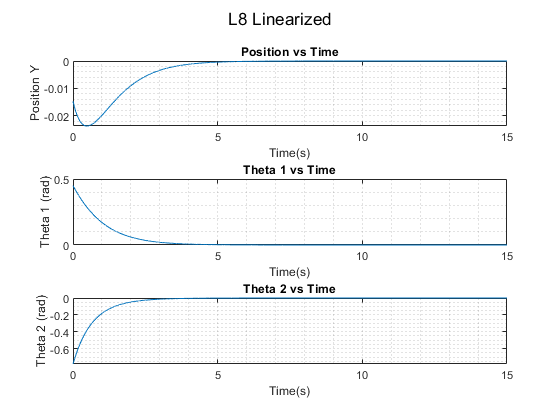

[t, x] = ode45(@(t,x) aae564hw5_2(x,A), time, x0);

subplot(3,1,1)
plot(t,x(:,1));
title('Position vs Time');
xlabel('Time(s)');
ylabel('Position Y');
grid minor;

subplot(3,1,2)
plot(t,x(:,2))
title('Theta 1 vs Time');
xlabel('Time(s)');
ylabel('Theta 1 (rad)');
grid minor;

subplot(3,1,3)
plot(t,x(:,3))
title('Theta 2 vs Time');
xlabel('Time(s)');
ylabel('Theta 2 (rad)')
grid minor;

sgtitle('L8 Linearized')

function x_dot = aae564hw5_2(x,A)
x_dot = A*x;
end